#  Find real world centroids & coordinates

This program uses an Xbox kinect 360 sensor to capture an image of a scene and output the real world coordinates of the centroid(s) of the items found.

## Capture image of scene with kinect

Get a snapshot from channel one, kinect RGB_640x480 video.

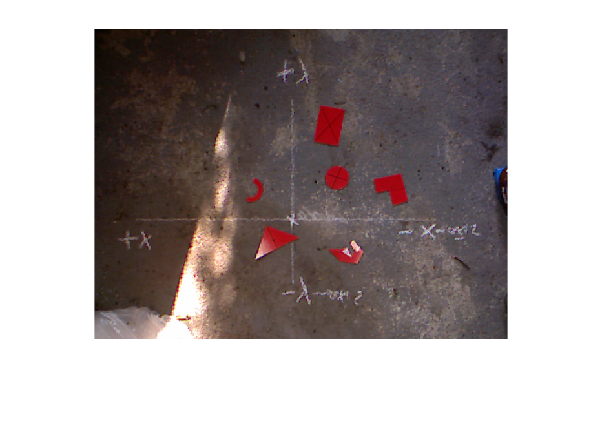

close all, clear all, clc
vid = videoinput('kinect',1,'RGB_640x480');
colorimg = getsnapshot(vid);
imshow(colorimg)

## Classiffy scene from object identified

The trained squeezent image classifier, classifies the object however it can only be used to classify a single object in the scene. This classifier outperformed the other networks that were trained on a portion of the TACO waste in thye wild dataset. 

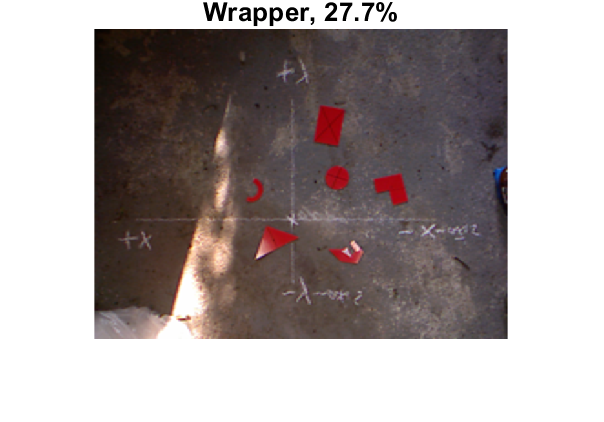

load trainedSqueezenet.mat
net = trainedNetwork;
inputSize = net.Layers(1).InputSize;
classNames = net.Layers(end).ClassNames;
new = imresize(colorimg,inputSize((1:2)));
[label,scores] = classify(net,new);
new = imresize(new,[480 640]);
figure
imshow(new)
title(string(label) + ", " + num2str(100*scores(classNames == label),3) + "%");

## Get point cloud of scene

A point cloud is a 3D reconstruction of a scene with RGB colour points. A minimum of two cameras are required to create a point could, more cameras result in a 'fuller' point cloud.

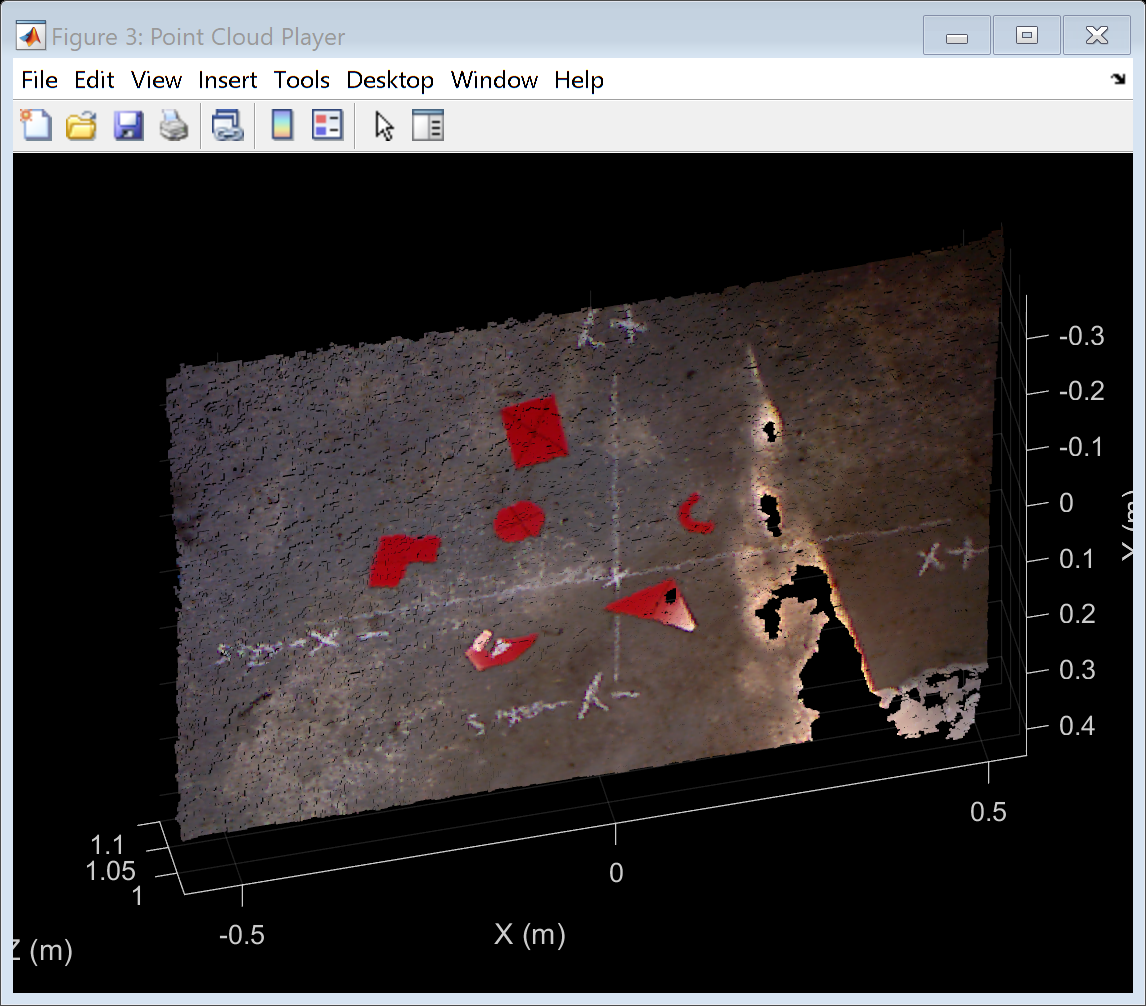

% Reference: https://uk.mathworks.com/help/vision/ref/pcfromkinect.html

colorDevice = imaq.VideoDevice('kinect',1,'RGB_640x480');
depthDevice = imaq.VideoDevice('kinect',2,'Depth_640x480');
step(colorDevice);
step(depthDevice);
colorImage = step(colorDevice);
depthImage = step(depthDevice);
ptCloud = pcfromkinect(depthDevice,depthImage,colorImage);
player = pcplayer(ptCloud.XLimits,ptCloud.YLimits,ptCloud.ZLimits,...
	'VerticalAxis','y','VerticalAxisDir','down');

xlabel(player.Axes,'X (m)');
ylabel(player.Axes,'Y (m)');
zlabel(player.Axes,'Z (m)');

  
colorImage = step(colorDevice);  
depthImage = step(depthDevice);
 
ptCloud = pcfromkinect(depthDevice,depthImage,colorImage);
 
view(player,ptCloud);

## Locate item(s)

The items are segmented using a special mask that is made to replicate the colour threshold mask created from IP. The filter size and shape can be a multitude of size and shapes however it will cause loss of information and cause errors in measurements, both pixel and real world. A filter is needed to remove noise in the image for blob analysis.

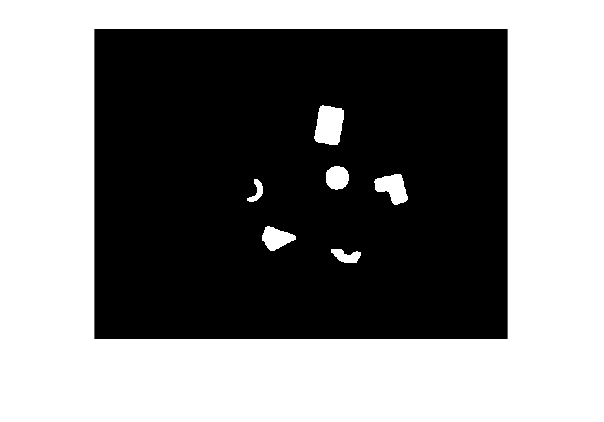

mask = kinecttest(colorimg);
filt = fspecial("disk",5);
new = imfilter(mask,filt,'replicate');
imshow(new)

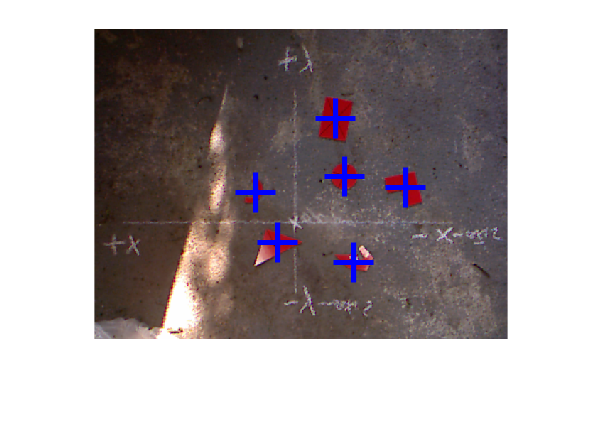


% Perform blob analysis to estimate blob parameters
blobAnalysis = vision.BlobAnalysis('AreaOutputPort', true,...
    'CentroidOutputPort', true,...
    'MinorAxisLengthOutputPort', true,...
    'BoundingBoxOutputPort', true,...
    'ExcludeBorderBlobs', true);
[areas,centroid,minor,boxes] = step(blobAnalysis, new);

% Sort connected components in descending order by area
[~, idx] = sort(areas, 'Descend');
item = label;

% Get the blobs.
boxes = double(boxes(idx(), :));

% Find the centroids of detected items.
centroids = round(centroid(:, :));
    %+ centroid(:, 3) / 2), ...
%    round(centroid(:, 2) + centroid(:, 4) / 2)];

% Find the 3-D world coordinates of the centroids.
length = numel(centroids(idx));
T = table(zeros(length,1),zeros(length,1),zeros(length,1),zeros(length,1),zeros(length,1),'VariableNames', {'twoDx','twoDy','threeDX','threeDY','threeDZ'});

figure, imshow(colorimg)
hold on
for i = 1:length
    T.twoDx(i,:) = centroids(i,1);
    T.twoDy(i,:) = centroids(i,2);
    ptCloudOut = select(ptCloud,T.twoDx(i,:),T.twoDy(i,:));
    trueCentroid = ptCloudOut.Location;
    T.threeDX(i,:) = trueCentroid(1,1);
    T.threeDY(i,:) = trueCentroid(1,2);
    T.threeDZ(i,:) = trueCentroid(1,3);
    plot(T.twoDx(i,:),T.twoDy(i,:),'b+', 'MarkerSize', 15, 'LineWidth',2);
end


disp(T)

    twoDx    twoDy     threeDX     threeDY     threeDZ
    _____    _____    _________    ________    _______

     252      253      -0.12502    0.020526     1.066 
     283      324     0.0073941    0.077638     1.056 
     364      150      -0.31633     0.22888     1.063 
     377      231      -0.16452      0.2514     1.056 
     390      352      0.058817     0.27387      1.05 
     462      247      -0.13456     0.40736     1.053 

